clear
close all
L=1e-4;
Kt = 0.2*1.5;Ke = Kt;
Ra = 0.1*1.5;
B = 0.01*1;
Jm = 3.5e-5+0.000005;
JpoleaConductora=0.06754e-4

JpoleaConductora = 6.7540e-06

Jext=33.74e-4

Jext = 0.0034

Kb = (Ke / (2 * pi * Kt));
L = (Ke * Kb) / Ra;
%L=1e-3
Jout=5e-3;

N=2

N = 2

Jt=Jm+JpoleaConductora+(Jext)/N^2;
Rinercia=(JpoleaConductora+(Jext)/N^2)/Jm

Rinercia = 21.2564

Vi=0

Vi = 0

Vf=24

Vf = 24

t0=0

t0 = 0

tf=5

tf = 5

clk=4000000

clk = 4000000

PWM=2000

PWM = 2000

TMR2_prescaler=2

TMR2_prescaler = 2

PR2=clk/(4*PWM*TMR2_prescaler)-1

PR2 = 249


sensibilidad=24/PR2

sensibilidad = 0.0964

nPuntos=251

nPuntos = 251



[Time, V_PWM]=perfil_voltaje(Vi/24*PR2, 0, 0, Vf/24*PR2, 0, 0, t0, tf,nPuntos);
ts=tf/(nPuntos-1)*1000

ts = 20

duty=100*0.01

duty = 1


V_PWM=round(V_PWM*duty,0)

V_PWM =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


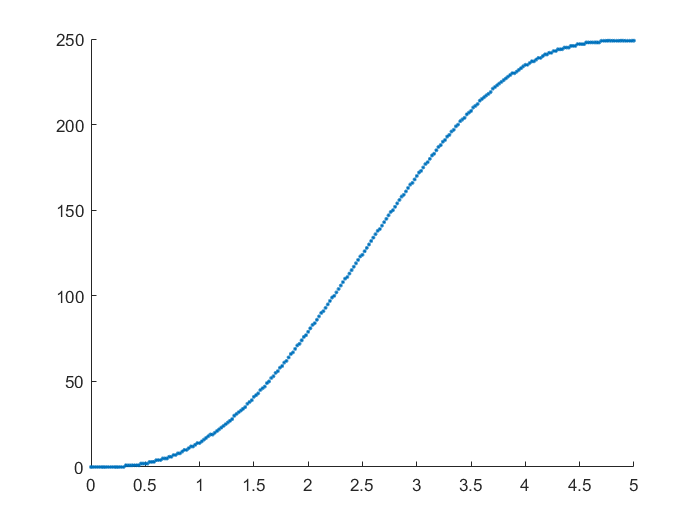


scatter(Time,V_PWM,".")

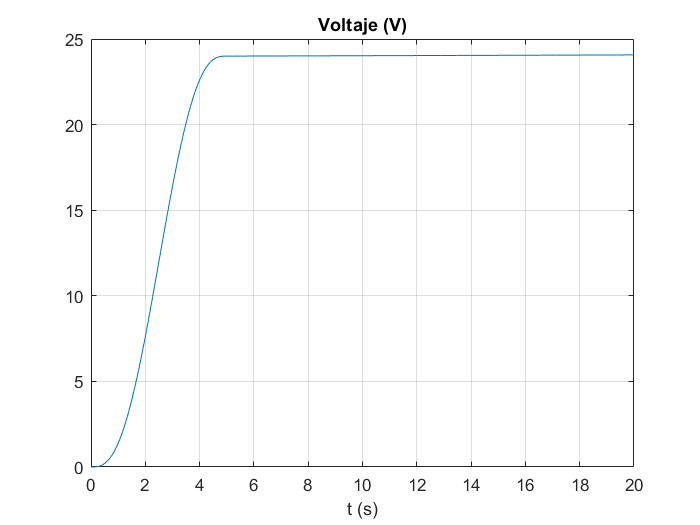



Vprofile=[Time, Vd];

sim("modelo.slx")


figure(1)

plot(Vprof.Time,Vprof.data)
xlabel("t (s)")
title("Voltaje (V)")
grid on

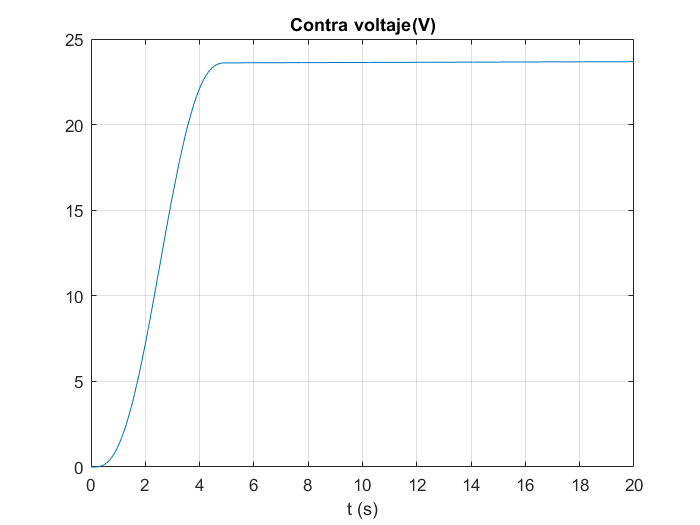


figure(2)

plot(Vcontra.Time,Vcontra.data)
xlabel("t (s)")
title("Contra voltaje(V)")
grid on

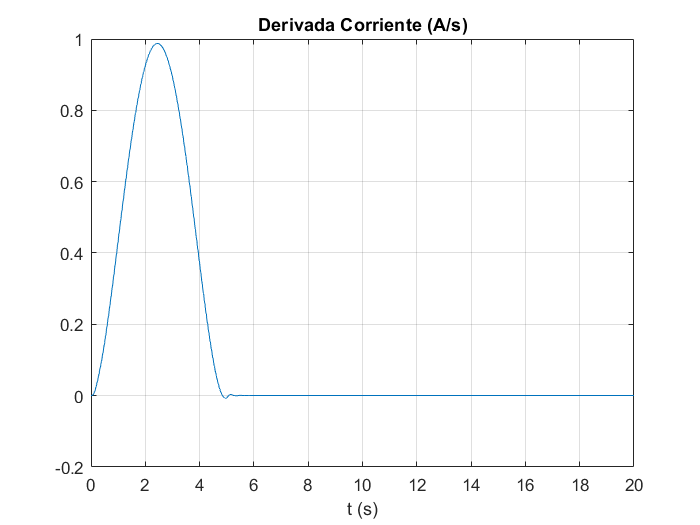



figure(3)

plot(Id.Time,Id.data)
xlabel("t (s)")
title("Derivada Corriente (A/s)")
grid on

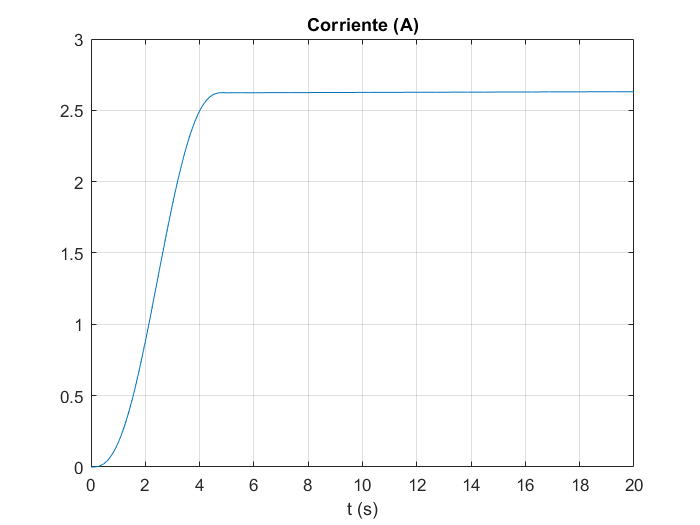



figure(4)

plot(I.Time,I.data)
xlabel("t (s)")
title("Corriente (A)")
grid on

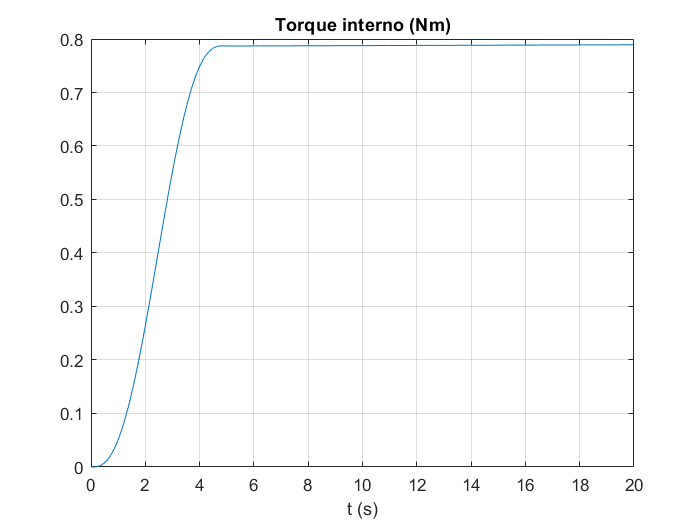





figure(5)
plot(Tau_in.Time,Tau_in.data)
title("Torque interno (Nm)")
xlabel("t (s)")
grid on

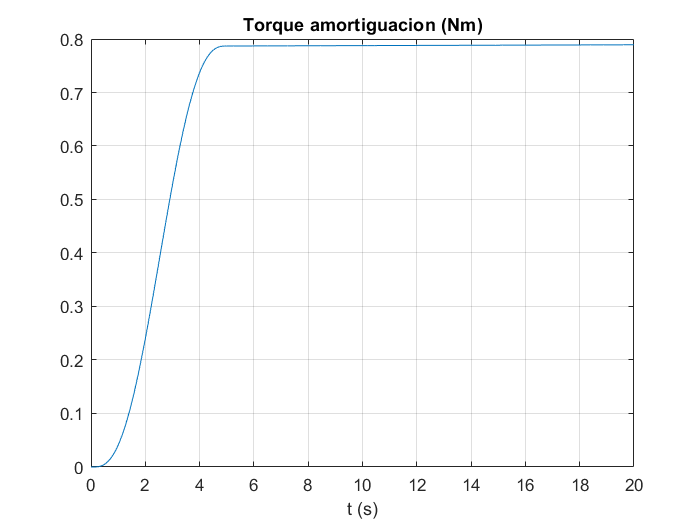




figure(6)
plot(Tamor.Time,Tamor.data)
title("Torque amortiguacion (Nm)")
xlabel("t (s)")
grid on

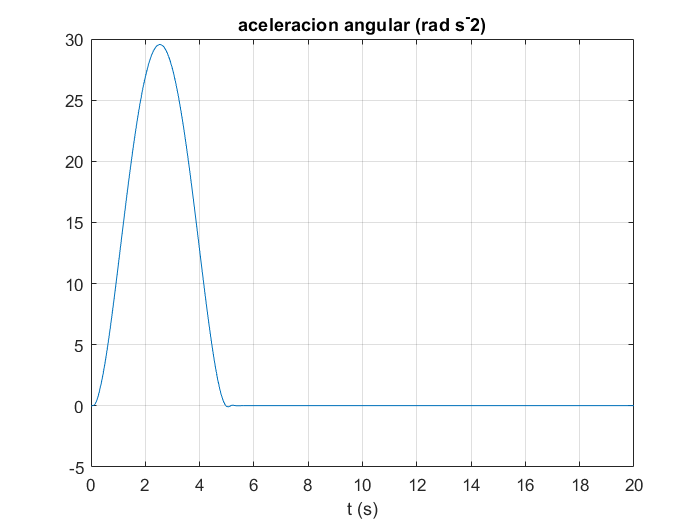


figure(7)
plot(qdd.Time,qdd.data)
title("aceleracion angular (rad s^-2)")
xlabel("t (s)")
grid on

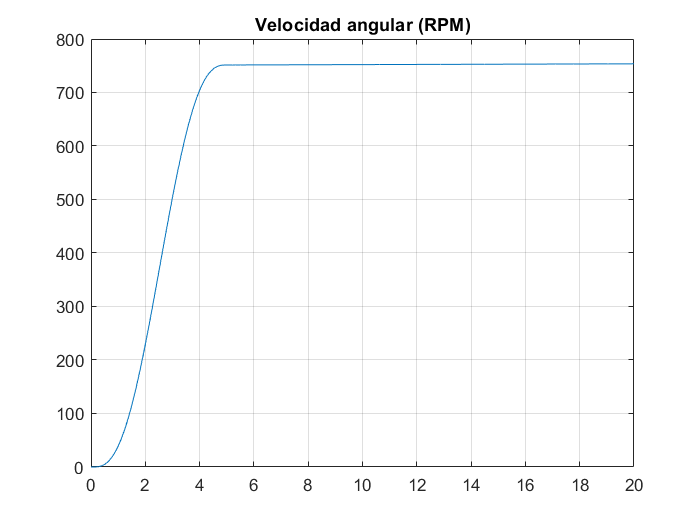




figure(8)
plot(qd.Time,qd.Data)
title("Velocidad angular (RPM)")
grid on

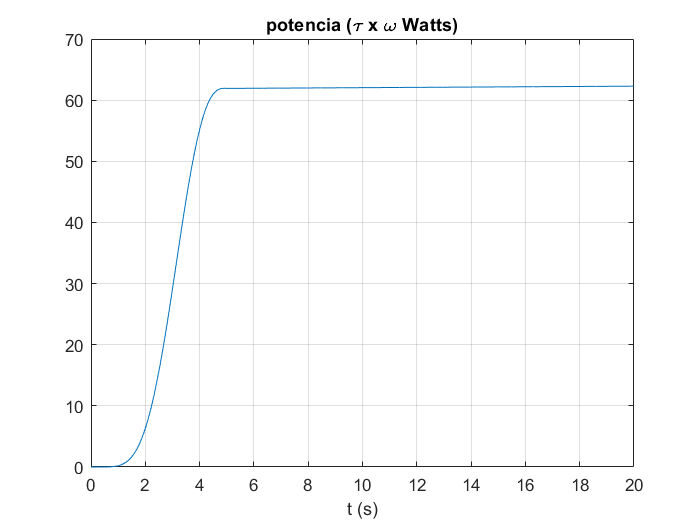



figure(9)
plot(potenciaMec.Time,potenciaMec.data)
title("potencia (\tau x \omega Watts)")
xlabel("t (s)")
grid on

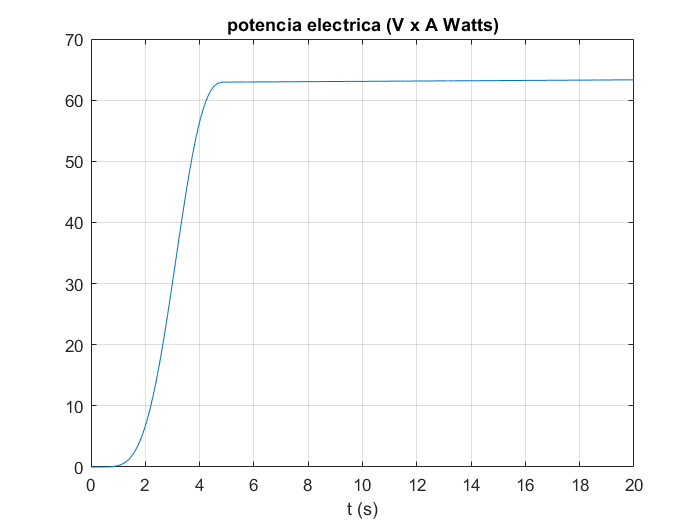




figure(10)
plot(potenciaElec.Time,potenciaElec.data)
title("potencia electrica (V x A Watts)")
xlabel("t (s)")
grid on

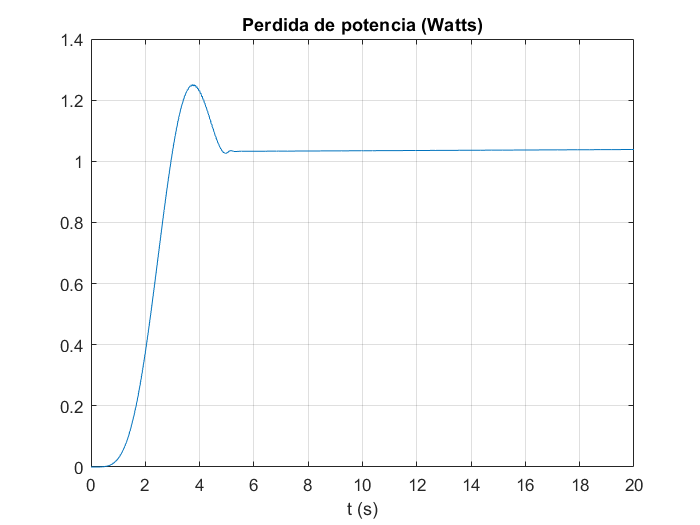


figure(11)

plot(potenciaElec.Time,potenciaElec.data-potenciaMec.data)
title("Perdida de potencia (Watts)")
xlabel("t (s)")
grid on

function [qd, vd, ad] = perfil_movimiento(q0, v0, ac0, q1, v1, ac1, t0, tf, npoints)

t = linspace(t0, tf, npoints);
c = ones(size(t));
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
      0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
      0 0 2 6*t0 12*t0^2 20*t0^3;
      1 tf tf^2 tf^3 tf^4 tf^5;
      0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
      0 0 2 6*tf 12*tf^2 20*tf^3];

b = [q0; v0; ac0; q1; v1; ac1];
a = M^-1 * b;

qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3 +a(5).*t.^4 + a(6).*t.^5;
vd = a(2).*c +2*a(3).*t +3*a(4).*t.^2 +4*a(5).*t.^3 +5*a(6).*t.^4;
ad = 2*a(3).*c + 6*a(4).*t +12*a(5).*t.^2 +20*a(6).*t.^3;

end


function [t,qd] = perfil_voltaje(q0, v0, ac0, q1, v1, ac1, t0, tf, npoints)

t = linspace(t0, tf, npoints)';
c = ones(size(t));
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
      0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
      0 0 2 6*t0 12*t0^2 20*t0^3;
      1 tf tf^2 tf^3 tf^4 tf^5;
      0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
      0 0 2 6*tf 12*tf^2 20*tf^3];

b = [q0; v0; ac0; q1; v1; ac1];
a = M^-1 * b;

qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3 +a(5).*t.^4 + a(6).*t.^5;

end


function [t,qd] = perfil_voltaje_C(q0, q1, tf, npoints)

t = linspace(0, tf, npoints)';
c = ones(size(t));
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
      0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
      0 0 2 6*t0 12*t0^2 20*t0^3;
      1 tf tf^2 tf^3 tf^4 tf^5;
      0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
      0 0 2 6*tf 12*tf^2 20*tf^3];

b = [q0; 0; 0; q1; 0; 0];
a = M^-1 * b;

qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3 +a(5).*t.^4 + a(6).*t.^5;

end









